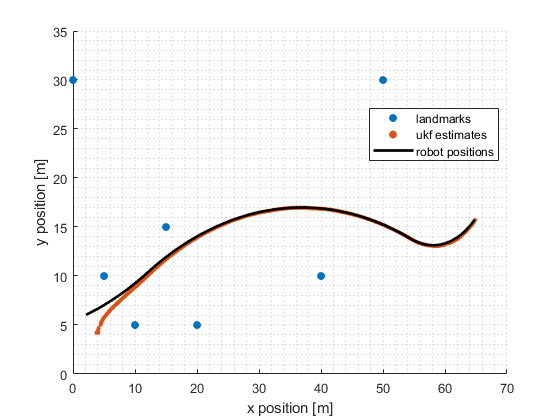

clear variables; close all;clc
% unscented kalman filter example 6
% tracking of a robot
% states = (position x, position y, orientation theta) = (x, y, theta)'
% control inputs = (commanded velocity, steering angle) =  (v, alpha)'

addpath('../utilities');

% time step [s]
dt = 0.1;

% number of input commands
n = 600;

% landmarks information
landmarks = [5 10; 10 5; 15 15; 20 5; 0 30; 50 30; 40 10]';

% dimensions
dim_x = 3;
dim_z = 2 * size(landmarks, 2);
dim_u = 2;

% input commands information
u = ones(dim_u, n);
u(:, 1:100) = u(:, 1:100).*[1.1 0.01]';
u(:, 101:500) = u(:, 101:500).*[1.1 -0.01]';
u(:, 501:600) = u(:, 501:600).*[1.1 0.05]';

% robot information
wheelbase = 0.5;
robot_pos = [2, 6, 0.3]';

% sensor information
range_std = 2;
bearing_std = 3;

% initial condition
% mean
x =  [4, 4, 0.3]';
% covariance
P = diag([0.1 0.1 0.05]);

% process noise covariance
Q = eye(3) * 0.0001;

% measure noise covariance
diag_values = repmat([range_std^2 bearing_std^2], 1, size(landmarks, 2));
R = diag(diag_values);
  
% (non linear) state transition function
f = @(x, u, dt, wheelbase) robot_move(x, u, dt, wheelbase);

% (non linear) measurement function
h = @(x, landmarks) h_robot(x, landmarks);

% sigma points deterministic sampling
alpha = 1e-5;
beta = 2;
kappa = 0;

% data structures
track = zeros(dim_x, n);
x_posterior = zeros(dim_x, n);
P_posterior = cell(1, n);

[Wm, Wc] = merwe_weights(alpha, beta, kappa, dim_x);

% define weighted mean angle function
wma = @(angles, weights) atan2(sin(angles) * weights', cos(angles) * weights');
    
% filtering
for ii = 1:n    
    % simulate new robot position (x, y, theta)
    robot_pos = robot_move(robot_pos, u(:, ii), dt, wheelbase);
        
    % build observations/measures
    z = robot_measure(robot_pos, landmarks, range_std, bearing_std, dim_z);
    
    % i) deterministic sampling from given mean and covariance (mass points)
    sigmas = robot_calculate_sigma_points(x, P, alpha, kappa, dim_x);
    
    % ii) predict:
    % (non linear) forward transition of the mass points (prediction)
    sigmas_f = f(sigmas, u(:, ii), dt, wheelbase);
   
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)  
    [x, P] = robot_unscented_transform(sigmas_f, Wm, Wc, Q, wma);
       
    % iii) update (correct)
    % (non linear) measurement space transformation of the mass forwarded points
    sigmas_h = h(sigmas_f, landmarks);
    
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)
    [zp, Pz] = robot_unscented_transform(sigmas_h, Wm, Wc, R, wma);
    
    % cross covariance
    Pxz = (sigmas_f-x) * diag(Wc) * (sigmas_h-zp)';
    
    % kalman gain
    K = Pxz/(Pz);
    
    % residual
    y = z - zp;
    y(2:2:end, :) = wrapToPi(y(2:2:end, :));
    
    % posterior mean
    x = x + K*y;
    
    % posterior covariance
    P = P - K*Pz*K';
    
    % saving
    track(:, ii) = robot_pos;
    x_posterior(:, ii) = x;
    P_posterior{ii} = P;
end

% plots
mP_posterior = cell2mat(P_posterior);
cols = 1:size(mP_posterior, 2);
cols = cols(mod(cols,3) ~= 0);
prob = normcdf(6)-normcdf(-6);

figure
hold on; grid minor;
scatter(landmarks(1, :), landmarks(2, :), 'filled');
scatter(x_posterior(1, :), x_posterior(2, :), 10, 'filled');
plot(track(1, :), track(2, :), 'k', 'LineWidth', 2);
% for ii = 1:10:n
%     [h, hc] = plot_covariance_ellipse(x_posterior(1:2, ii), mP_posterior(1:2, cols(2*ii-1:2*ii)), prob);
%     h.set('Color', 'r');
%     hc.set('Color', 'r')
% end
xlabel('x position [m]');
ylabel('y position [m]')
xlim([0 70])
ylim([0 35])
legend('landmarks', 'ukf estimates', 'robot positions', 'location', 'best')